# **Assignment: **Phylogenetic trees

## Bianca Caissotti di Chiusano

Pick a different subset of data from the nextstrain site, download the metadata file and clean it up (see the process I noted I used at the top of this script), so it can be used to build a tree - you may wish to select only a subset of the data, for computational reasons (especially if the sequences are long).  Upload your metadata file with your assignment.  

State a research question you want to explore using your chosen dataset (and that can be answered by building a phylogenetic tree).  

Then build a phylogenetic tree to answer your research question and draw some conclusions from your investigation.  

#### Introduction

In March 2014 cases of Ebola Virus Disease were reported in southeastern Guinea. From our data the first case goes back to the 17th of March 2014 in the division of Kissidougou. 

For the purpose of this assignment, we will see how the Ebola disease changes from the beginning in March, to end of December 2014 in that same division where is all began for the country of Guinea. 

To achive this dataset, I firstly downloaded the metadata for Ebola from this link: [https://nextstrain.org/ebola](https://nextstrain.org/ebola)

This gave me a dataset of 1494 cases of the 2014 and 2015 cases in countries of West Africa and their divisions. To filter out the data, and get to the current research question I first ordered the data in Chronological order (from oldest to newest) and deleted all of the cases reported from January 2015. This brought the dataset from 1494 cases to 902. 

I then restricted the cases to only the ones reported in Guinea, bringing the dataset to 229 cases, and finally deleted all cases that were not reported in the division of Kissidougou. Finally, ending with 12 cases, from March 17th to December 27th 2014.

EDIT: While working on this assignment, I thought it would also be interesting to briefly check if we can see how the virus was spread from Guinea to Liberia and Sierra Leone. This will be at the end of this script.

I turned the file into csv and created the following table by importing it into MATLAB.

ebola_guinea = readtable("nextstrain_ebola_metadata_reduced.csv")

ebola_guinea = 12×7 table
          strain              date        country         division        url                                 author                                  accession  
    ___________________    __________    __________    _______________    ___    ________________________________________________________________    ____________

    {'Kissidougou-C15'}    17/03/2014    {'Guinea'}    {'Kissidougou'}    NaN    {'Baize et al (https://www.ncbi.nlm.nih.gov/pubmed/24738640)'  }    {'KJ660346'}
    {'EM_079444'      }    02/04/2014    {'Guinea'}    {'Kissidougou'}    NaN    {'Carroll et al (https://www.ncbi.nlm.nih.gov/pubmed/26083749)'}    {'KR817193'}
    {'EM_078694'      }    14/12/2014    {'Guinea'}    {'Kissidougou'}    NaN    {'Carr

% Number of datapoints 
accession_nums = (height(ebola_guinea))

accession_nums = 12

For all cases, I got the sequence with the command **getgenbank** and added these sequences to a separate table.

seq= getgenbank("KJ660346", "SequenceOnly",true);
table_seq = table({seq}, 'VariableNames', {'Sequences'});
for i = 2 : 12
    tmp_arr = ebola_guinea.accession(i);
    str = string(tmp_arr(1));
    table_seq.Sequences{i} = getgenbank(str, "SequenceOnly",true);
end

To construct the phylogenetic trees, we will be using a Distance-Based method so we first construct a method containing the distances between each pair of sequence

The command **seqpdist** is used to calculate the pairwise distance between sequences.

By setting 'SquareForm' to true, we are converting the output into a square matrix. It is going to be a 12x12 matrix, as we are dealing with 12 sequences.

The default method used for this command is called the Jukes-Cantor method. According to the documentation, this method calculates the "Maximum likelihood estimate of the number of substitutions between two sequences". To some extent, it is similar to the p-distance method where the distance = p, and "p is close to 1 for poorly related sequences or 0 for similar sequences".

distances = seqpdist(table_seq.Sequences, 'SquareForm',true)

distances =          0    0.0003    0.0008    0.0022    0.0021    0.0052    0.0007    0.0044    0.0048    0.0023    0.0023    0.0007
    0.0003         0    0.0011    0.0024    0.0023    0.0054    0.0011    0.0047    0.0050    0.0025    0.0025    0.0011
    0.0008    0.0011         0    0.0014    0.0013    0.0043    0.0001    0.0036    0.0039    0.0014    0.0014    0.0001
    0.0022    0.0024    0.0014         0    0.0002    0.0031    0.0015    0.0023    0.0025    0.0002    0.0002    0.0015
    0.0021    0.0023    0.0013    0.0002         0    0.0031    0.0013    0.0024    0.0027    0.0002    0.0002    0.0013
    0.0052    0.0054    0.0043    0.0031    0.0031         0    0.0044    0.0033    0.0035    0.0031    0.0031    0.0044
    0.0007    0.0011    0.0001    0.0015    0.0013    0.0044         0    0.0037    0.0040    0.0015    0.0015         0
    0.0044    0.0047    0.0036    0.0023    0.0024    0.0033    0.0037         0    0.0003    0.0024    0.0024    0.0037
    0.0048    0.0050

For example, we can observe that seq1 (Kissidougou-C15) and seq3(EM_078694)  have a distance of 0.0008, while seq1 and seq4 (EM_078706)  of 0.0022, thus seq1 is closer to seq3 rather than seq4.

A colorbar is used for a more visual representation of the distances matrix. On the diagonal we can observe the darkest color, as when comparing two same sequences, the distance is 0. Thus dark colours signify closeness in distance, while on the yellow side signifies that the pair of sequences are more distant. It is also important to notice that the figure (and matrix) is symmetrical, thus the two sides of the diagonal represent the same numbers.

We can see that the first few sequences, are quite related, or close to each other, while those same sequences are further in distance compared to what seems around sequences 8-10, where there is a yellow block.

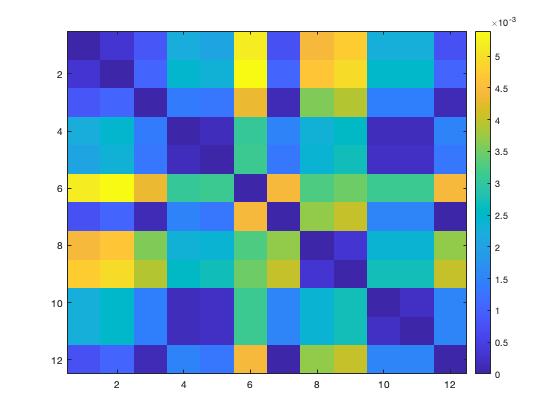

imagesc(distances)
colorbar

**The phylogenetic tree problem is the following:** "If we are given a set of sequences and the calculated genetic distances between them.  How can we build a tree showing the relationships between the sequences?"

As previously mentioned, we are using distance based methods such as UPGMA with the command **seqlinkage**, and neighbour-joining with the command **seqneighjoin.**

Starting first with UPGMA, we will plot 4 phylotrees with the following 4 methods:

- Single Linkage Method: Nearest Distance

- Complete Linkage Method: Furthest Distance

- UPGMA Group Average: Unweighted Pair Group Method Average

- WPGMA: Weighted Pair Group Method Average 

Later I will look at the Neighbour joining method

I want to note however, that I mainly considered the trees from the Single Linkage Method and the Neighbour Joining Method, eventhough other trees were plotted out of interest.

#### Single Linkage Method: Nearest Distance

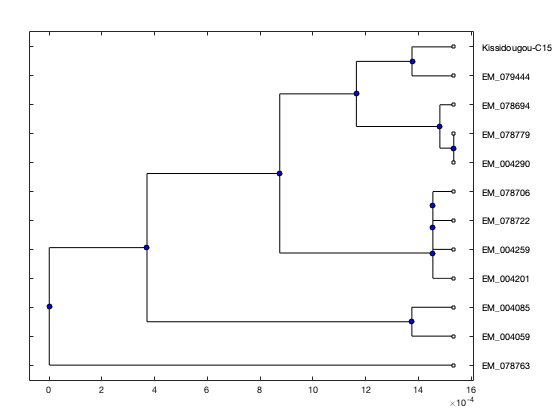

phyloTree = seqlinkage(distances,'single', ebola_guinea.strain);
plot(phyloTree)

To understand this phylogenetic tree better, below is an image of the same plotted tree, but with the dates of the reported ebola cases in the division of Kissidougou. 

It makes sense that the first two cases (in march and april 2014) are paired together and have a common ancester and are close in distance. Moreover, we can see that the case reported on the 17th of december is the furthest away from the first two reported cases. The latter could also be a "new" variation of the virus as it isn't necessarily paired with any other sequence.

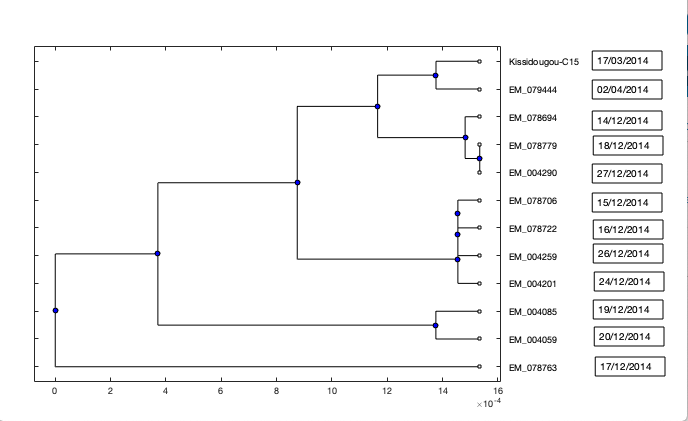

#### Complete Linkage Method: Furthest Distance

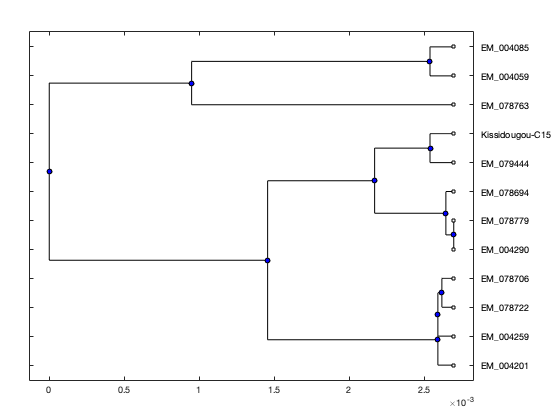

phyloTree_complete = seqlinkage(distances,'complete', ebola_guinea.strain);
plot(phyloTree_complete)

#### Average: Unweighted Pair Group Method Average (UPGMA, group average).

phyloTree_average = seqlinkage(distances,'average', ebola_guinea.strain);
plot(phyloTree_complete)

#### Weighted: Weighted Pair Group Method Average (WPGMA)

phyloTree_weighted = seqlinkage(distances,'weighted', ebola_guinea.strain);
plot(phyloTree_complete)

#### Neighbour Joining Equivar 

With the seqneighjoin command we can plot a phylogenetic tree using the neighbor-joining method. I believe this method is more intuitive and realistic compared to the methods seen above. This is because it lets us observe and represents the actual branch lengths in the trees. 

This first tree uses the equivar method. The two possible methods for the NJ on matlab seem to be the equivar and first order method which are different ways of computing distances between the nodes. Out of curiosity I plotted both.

According to the documentation: The equivar method "assumes equal variance and independence of evolutionary distance estimates".

Reading: (Saitou, N., and Nei, M. (1987). The neighbor-joining method: A new method for reconstructing phylogenetic trees. Molecular Biology and Evolution 4(4), 406–425.)

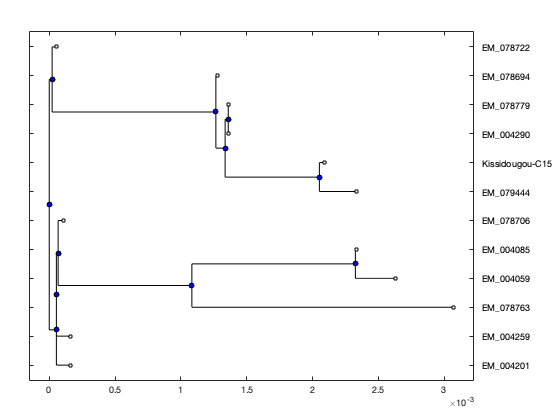

phyloTree_neigh = seqneighjoin(distances,'equivar',ebola_guinea.strain);
plot(phyloTree_neigh)

Again, for this tree, I wanted to visualise the dates of the reported cases. We can observe, that the conclusions are more or less similar to the results seen from the single linkage method tree, were the first two cases of march and april are close, while some cases from december 2014 seem to be much farther than the initial reported cases. For example, again the reported case on the 17th of april. If we track the branch lengths from that case to the march case, it is the longest in distance, just represented in a different way.

Overall, I would say that NJ is more intuitive. Thinking about my research question, I believe that if I could change something, I would probably look at how the virus changes through the course of the whole outbreak (restricting it to Guinea and the Kissidougou district), thus looking at 2014-2016, eventhough that would imply a much larger dataset. These 12 cases reported in Kissidougou throughout 2014 however still should how much the virous changed throughout the year, even just looking at how distance some cases from just a matter of days are.

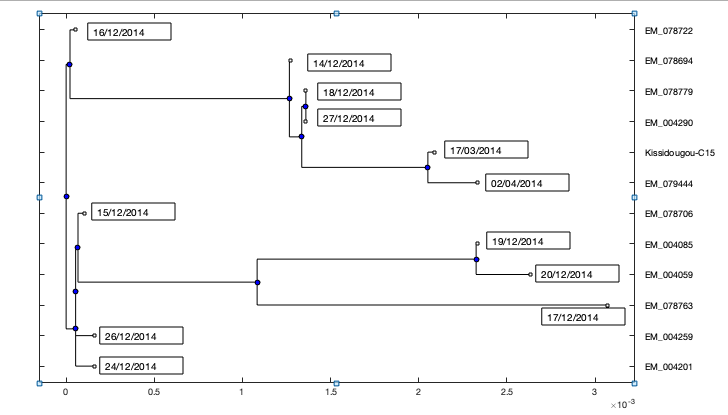

#### Neighbour Joining First Order 

According to the documentation: The firstorder method "assumes a first order model of the variances and covariances of evolutionary distance estimates".

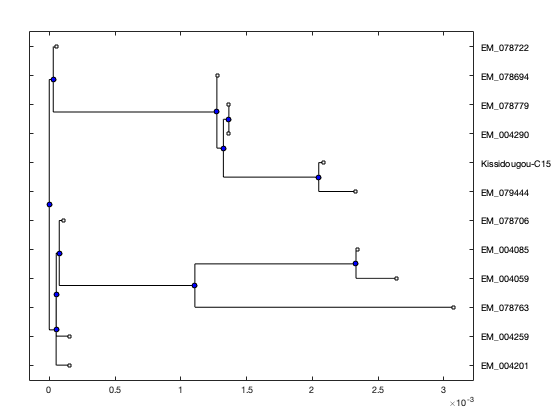

phyloTree_neigh = seqneighjoin(distances,'firstorder',ebola_guinea.strain);
plot(phyloTree_neigh)

### Another Idea

This was the second Idea mentioned in the introduction.

For the purpose of this assignment, I am aware that I had to choose only one research question, however I still decided to include this little analysis (hope its not a problem).

I decided to look at the first 5 reported cases for each country (Guinea, Liberia, Sierra Leone), ending with a dataset of 15 points.

The same commands and thinking were brought out as described before to read the table and compute the distances between the sequences.

ebola_per_country = readtable("first5perCountry_ebola.csv")

ebola_per_country = 15×7 table
          strain              date           country            division        url                                 author                                  accession  
    ___________________    __________    ________________    _______________    ___    ________________________________________________________________    ____________

    {'Kissidougou-C15'}    17/03/2014    {'Guinea'      }    {'Kissidougou'}    NaN    {'Baize et al (https://www.ncbi.nlm.nih.gov/pubmed/24738640)'  }    {'KJ660346'}
    {'Gueckedou-C05'  }    19/03/2014    {'Guinea'      }    {'Gueckedou'  }    NaN    {'Baize et al (https://www.ncbi.nlm.nih.gov/pubmed/24738640)'  }    {'KJ660348'}
    {'Gueckedou-C07'  }    20/03/2014    {'Guinea'      } 

seq= getgenbank("KJ660346", "SequenceOnly",true);
table_seq_country = table({seq}, 'VariableNames', {'Sequences'});
for i = 2 : 15
    tmp_arr = ebola_per_country.accession(i);
    str = string(tmp_arr(1));
    table_seq_country.Sequences{i} = getgenbank(str, "SequenceOnly",true);
end

distances_country = seqpdist(table_seq_country.Sequences, 'SquareForm',true)

distances_country =          0    0.0003    0.0002    0.0017    0.0004    0.0003    0.0016    0.0003    0.0039    0.0005    0.0038    0.0022    0.0104    0.0017    0.0007
    0.0003         0    0.0002    0.0017    0.0004    0.0004    0.0019    0.0005    0.0042    0.0008    0.0041    0.0024    0.0107    0.0020    0.0009
    0.0002    0.0002         0    0.0015    0.0002    0.0003    0.0018    0.0004    0.0041    0.0007    0.0040    0.0023    0.0106    0.0019    0.0008
    0.0017    0.0017    0.0015         0    0.0016    0.0017    0.0006    0.0019    0.0029    0.0021    0.0028    0.0012    0.0093    0.0008    0.0015
    0.0004    0.0004    0.0002    0.0016         0    0.0003    0.0017    0.0005    0.0041    0.0006    0.0041    0.0024    0.0106    0.0020    0.0009
    0.0003    0.0004    0.0003    0.0017    0.0003         0    0.0017    0.0005    0.0041    0.0006    0.0041    0.0024    0.0106    0.0020    0.0009
    0.0016    0.0019    0.0018    0.0006    0.0017    0.0017         0    

I only looked this time at the NJ method to compute the phylogenetic tree.

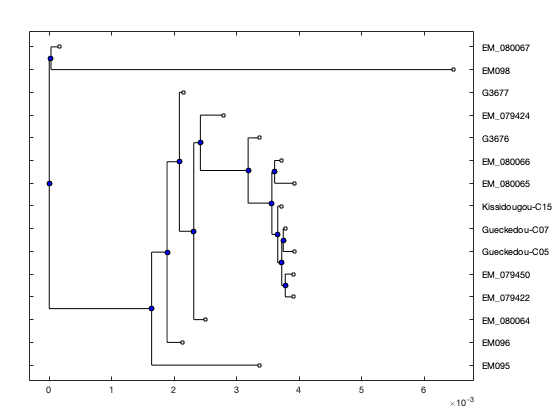

phyloTree_neigh_country = seqneighjoin(distances_country,'equivar',ebola_per_country.strain);
plot(phyloTree_neigh_country)

Again, to understand the tree better I added the dates of the reported cases in the three countries at each node.

The aim of this tree was to see if I could understand how the virus spread to each country, in other words, if it first entered Liberia or Sierra Leone from Guinea. 

The observations that caught my eye was the closness of the sequences of the first few cases, thus the cases in Guinea from the 17th, 19th, 20th and 27th of March. What we can clearly see is that the first case in Liberia on the 1st of april 2014 is very close in distance to those other cases, which are also close in dates. 

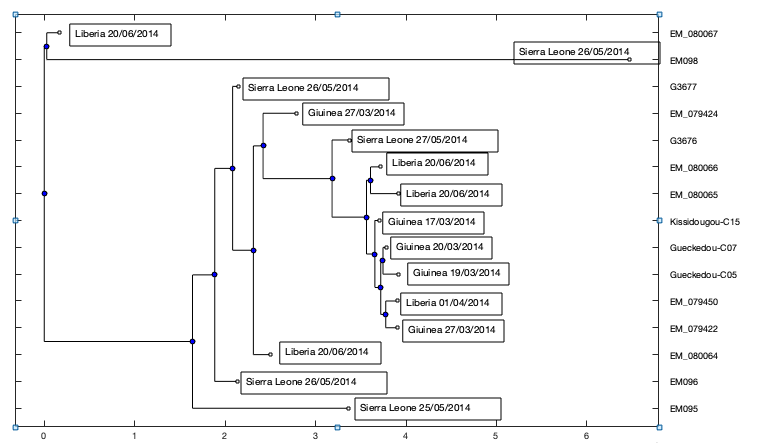

I then went to see the district of the reported case on the 27th of march 2014 in Guinea which was "Macenta". The map below shows a pindrop of this district and it is extremely close to Liberia. From this Phylogenetic tree and this last observation, I would thus conclude that the first case of ebola in Liberia was probably spread from this district of Guinea.